# **Parrando's Paradox**

addpath ../dablab_files/dablab_repo/
latex_interpreter

budget0 = 1;
bet = 0.01; %for now the bet is a the same for every game ...
%and in equal magnitude for win and losses in each game
maxTurns = 100000;
num_games = 2; %number of distinct games to choose ...
%from every turn
def_play_prob = 1/num_games; %a default probability ...
% of selecting a particular game


#### Fix Game A Parameters

p_play_a = 0.89;

p_win_a = 18/38; %either red or black
p_lose_a = 1-p_win_a;

exp_a = bet*p_win_a - bet*p_lose_a

exp_a = -5.2632e-04

#### Fix Game B Parameters

p_play_b = 1 - p_play_a;
m = 3; %a parameter which helps decide ...
% which game from B1 and B2 to play
p_play_b1 = 1/m;
p_play_b2 = 1- p_play_b1;

p_win_b1 = 4/38;
p_lose_b1  = 1-p_win_b1;

p_win_b2 = (18+9+2)/38; %18 numbers of either red/black, ...
%9 even or odd numbers of the other colour, ...
%and two green numbers
p_lose_b2 = 1-p_win_b2;

exp_b = ...
    p_play_b1*(bet*p_win_b1 - bet*p_lose_b1) + ...
    p_play_b2*(bet*p_win_b2 - bet*p_lose_b2)

exp_b = 8.7719e-04

#### Run the simulation

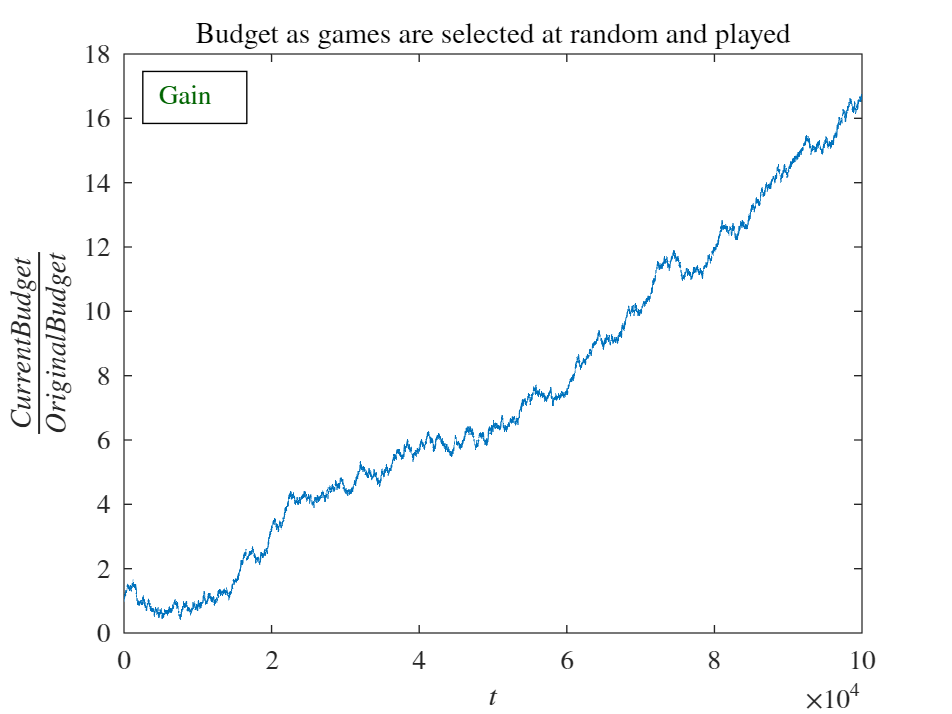

budgetArray = zeros(maxTurns,1);

budget = budget0;
budgetArray(1) = budget0;
turn = 0;

while budget >= bet && turn < maxTurns
    turn =  turn + 1;
    choose_game = rand;
    throw = rand;
    if choose_game <= p_play_a %play game A
        budget = budget + play(throw, p_win_a, bet);
    elseif choose_game <= p_play_a + p_play_b %play game B
        if mod(budget/bet, m) == 0 %play game B1
            budget = budget + play(throw, p_win_b1, bet);
        else %play game B2
            budget = budget + play(throw, p_win_b2, bet);
        end
    else
        print('Do Nothing.')
    end
    budgetArray(turn) = budget;
end

turns = 1:turn;


strLoss = 'Loss';
strGain = 'Gain';
strEqual = 'Evened out losses and gains';

if budget > 1
    str = strGain;
    col = [0, 100, 0]/255;
elseif budget < 1
    str = strLoss;
    col = 'red';
else
    str = strEqual;
    col = 'k';
end

figure('Name','Parrando''s Paradox in Action')
plot(turns, budgetArray(turns));
title('Budget as games are selected at random and played');
xlabel('$t$');
ylabel('$\frac{Current Budget}{Original Budget}$');

dim = [0.15 .70 .20 .20];
a = annotation('textbox', dim, 'String', str, 'FitBoxToText', 'on');
a.Color = col;

A simple function which will calculate

function change = play(throw, p_win, bet)
    if throw <= p_win
        change = bet;
    else
        change = -bet;
    end
end